# PINEM probability from total E-field calculation

close all


## Input

data = [0.75e-6, 1.1387, 0.9079e-06;
        1.0e-6, 1.2246, 1.0604e-06;
        1.25e-6, 1.2805, 1.2296e-06;
        1.5e-6, 1.3163, 1.3970e-06;
        1.75e-6, 1.3437, 1.5830e-06;
        2.0e-6, 1.3636, 1.7737e-06];

% Select taper diameter (micron)
diam =1*1e-6;                   

% Select PINEM-interaction to plot
interaction = "Tx";

P = 2;                          % Input power (W)
d = 0.03e-6;                    % Distance between e-beam and taper


## Parameters

% Constants
q = 1.60217663e-19;             % (C) electron charge
hbar = 1.054571817e-34;         % (J*s) reduced Plank constant
hbar_eV = 6.582119e-16;         % (eV) reduced Plank constant in eV
c0 = 2.998e8;                   % (m/s) speed of light
m = 9.109e-31;                  % (kg) electron mass

% Fiber parameters
data_idx = find(ismembertol(data(:,1), diam, 1e-7), 1, 'first');
n_eff = data(data_idx, 2);      % Effective refractive index
MFD = data(data_idx, 3);        % Mode field diameter (m)
lambda = 1.55e-6;               % Wavelength (m)
k0 = 2 * pi / lambda;           % Free-space wavenumber
n2 = 1.444;                     % Cladding refractive index
n3 = 1.0;                       % Surrounding refractive index 
eps0 = 8.8542e-12;              % Free-space permittivity
omega = 2 * pi * c0 / lambda;   % Angular frequency

b = diam / 2;                   % Cladding radius (m)
a = b / 15.24;                  % Core radius (m) 
beta = k0 * n_eff;              % Propagation constant: k0 * n_eff

v = 1;                          % Mode order = 1 for HE11

%Electron beam parameters
E_el = 200e3;                   % (eV) Electron beam kinetic energy
dE_el = 0.95;                   % (eV) Electron beam energy spread
v_fac = sqrt(1 - (m * c0^2 / ...
    (E_el * q + m * c0^2))^2);  % Electron velocity factor
v_e = c0 * v_fac;               % (m/s) Electron velocity
k_e = omega / v_e;              % (m^-1) Electron wave vector. Phase matching condition.
r = b + d;                      % Radial position of e-beam

% Core field amplitude
I = 4 * P / (pi * MFD^2);                   % (W/m^2) Laser intensity
E0 = sqrt(2 * I / (c0 * n_eff * eps0));     % (V/m) Electric field amplitude

% Fiber wavenumbers
U = b * sqrt(k0^2 * n2^2 - beta^2);         % Core wavenumber 
W = b * sqrt(beta^2 - k0^2 * n3^2);         % Cladding decay constant 
V = 2*pi * b/lambda * sqrt(n2^2 - n3^2);    % Cladding fiber parameter 

% Bessel coefficients
b1 = 1/(2*U*besselj(v,U)) * (besselj(v-1,U) - besselj(v+1,U));
b2 = -1/(2*W*besselk(v,W)) * (besselk(v-1,W) + besselk(v+1,W));
F2 = (V/(U*W))^2 * v/(b1 + b2);
a1 = (F2 - 1)/2;
a2 = (F2 + 1)/2;

% 2D heat map of field
grid_size = sqrt(2) * MFD;      % Evaluate at 4 * sigma        
resolution = 200;              
x = linspace(-grid_size, grid_size, resolution);
y = linspace(-grid_size, grid_size, resolution);
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
Phi = atan2(Y, X);

% Initialize 2D field array
E_r_2D = zeros(size(R));
E_phi_2D = zeros(size(R));
E_z_2D = zeros(size(R));


## Fields

% Cladding field
clad_idx = (R <= b);
E_r_2D(clad_idx) = -1 / besselj(v, U) * ...
    (a1 * besselj(v-1, U * R(clad_idx) / b) + ...
     a2 * besselj(v+1, U * R(clad_idx) / b)) .* cos(v * Phi(clad_idx));
E_phi_2D(clad_idx) = -1 / besselj(v, U) * ...
    (a1 * besselj(v-1, U * R(clad_idx) / b) - ...
     a2 * besselj(v+1, U * R(clad_idx) / b)) .* -sin(v * Phi(clad_idx));
E_z_2D(clad_idx) = -1j * U/(b*beta) * besselj(v, U * R(clad_idx) / b) / ...
    besselj(v,U) .* cos(v * Phi(clad_idx));

% Evanescent field 
ev_idx = (R > b);
E_r_2D(ev_idx) = -U / (W * besselk(v, W)) * ...
    (a1 * besselk(v-1, W * R(ev_idx) / b) - ...
     a2 * besselk(v+1, W * R(ev_idx) / b)) .* cos(v * Phi(ev_idx));
E_phi_2D(ev_idx) = -U / (W * besselk(v, W)) * ...
    (a1 * besselk(v-1, W * R(ev_idx) / b) + ...
     a2 * besselk(v+1, W * R(ev_idx) / b)) .* -sin(v * Phi(ev_idx));
E_z_2D(ev_idx) = -1j * U/(b*beta) * besselk(v, W * R(ev_idx) / b) / ...
    besselk(v,W) .* cos(v * Phi(ev_idx));

% Total field vector
E_vec = cat(3, E_r_2D, E_phi_2D, E_z_2D);
E_vec_cart = cat(3, ...
    E_r_2D .* cos(Phi) - E_phi_2D .* sin(Phi), ...
    E_r_2D .* sin(Phi) + E_phi_2D .* cos(Phi), ...
    E_z_2D);


## Power/Amplitude normalization

% % Integration step sizes
% dr = grid_size * 2 / resolution;  
% dphi = 2 * pi / resolution;  
% 
% dx = dr;  
% dy = R .* dphi;  
% 
% % Power density (W/m²)
% S = (beta / (2 * omega * mu_0)) * sum(E_vec.^2, 3);  
% S_cart = (beta / (2 * omega * mu_0)) * sum(E_vec_cart.^2, 3);  
% 
% % Total power before scaling
% P_total = real(sum(sum(S .* R .* dr .* dphi)));
% P_total_cart = real(sum(sum(S_cart .* dx .* dy)));
% disp(['Input power: ', num2str(P), ' W']);
% disp(['Calculated power before scaling: ', num2str(P_total_cart), ' W']);

% % Scale total E-field according to power-matching
% E_vec = E_vec * sqrt(P / P_total);
% E_vec_cart = E_vec_cart * sqrt(P / P_total_cart);

% % New power density (W/m²)
% S = (beta / (2 * omega * mu_0)) * sum(E_vec.^2, 3);  
% S_cart = (beta / (2 * omega * mu_0)) * sum(E_vec_cart.^2, 3);  
% 
% % Total power after scaling
% P_total = real(sum(sum(S .* R .* dr .* dphi)));
% P_total_cart = real(sum(sum(S_cart .* dx .* dy)));
% disp(['Calculated power after scaling: ', num2str(P_total_cart), ' W']);

% Field magnitudes
E_mag = sqrt(sum(E_vec.^2, 3));
E_mag_cart = sqrt(sum(E_vec_cart.^2, 3));

% Normalize total E-field
E_vec = E_vec / max(E_mag(:));
E_vec_cart = E_vec_cart / max(E_mag_cart(:));

% Scale total E-field with amplitude from input power
E_vec = E_vec * E0;
E_vec_cart = E_vec_cart * E0;

% Recompute (component) magnitudes
E_mag = sqrt(sum(E_vec.^2, 3));
E_mag_cart = sqrt(sum(E_vec_cart.^2, 3));

E_r = E_vec(:,:,1);
E_phi = E_vec(:,:,2);
E_z = imag(E_vec(:,:,3));

E_x = E_vec_cart(:,:,1);
E_y = E_vec_cart(:,:,2);
E_t = sqrt(E_vec(:,:,1).^2 + E_vec(:,:,2).^2);

disp(['Peak amplitude: ', num2str(max(E_mag(:))),' V/m']);

Peak amplitude: 37327399.1078 V/m


## 2D Plot

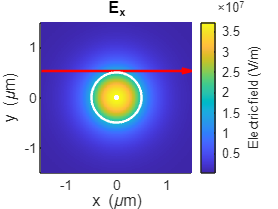

% 2D Plot
figure; hold on; box on;
if interaction == "Tx"
    imagesc(x * 1e6, y * 1e6, E_x);
    % Electron trajectory:
    arrow_x = min(x) * 1e6;
    arrow_y = r * 1e6;   
    arrow_length = 2 * grid_size * 1e6;  
    quiver(arrow_x, arrow_y, arrow_length, 0, ...
    'Color', 'r', 'LineWidth', 1.5, 'MaxHeadSize', 0.2, 'AutoScale', 'off');
    title('E_x');
end
if interaction == "Ty" 
    imagesc(x * 1e6, y * 1e6, E_y);
    % Electron trajectory:
    arrow_x = r * 1e6;  
    arrow_y = -min(y) * 1e6;  
    arrow_length = 2 * grid_size * 1e6;  
    quiver(arrow_x, arrow_y, 0, -arrow_length, ...
    'Color', 'r', 'LineWidth', 1.5, 'MaxHeadSize', 0.2, 'AutoScale', 'off');
    title('E_y');
end
if interaction == "Lz" 
    imagesc(x * 1e6, y * 1e6, imag(E_z));
    % Electron trajectory indicator:
    plot(r * 1e6, 0, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
    title(['E_z, diam. ',num2str(2*b*1e6),' \mum']);
end
viscircles([0, 0] * 1e6, a * 1e6, 'LineWidth', 0.5, 'Color', 'w'); % Show core 
viscircles([0, 0] * 1e6, b * 1e6, 'LineWidth', 0.5, 'Color', 'w'); % Show cladding
axis equal tight;
colormap default;
color=colorbar;
color.Label.String = 'Electric field (V/m)';
xlabel('x (\mum)');
ylabel('y (\mum)');
hold off;


% matlab2tikz('D:\Documents\Study\Graduation project\MATLAB\Export\PINEM_Ex_ebeam.tex',...
%     'relativeDataPath', 'Figures','showInfo', false,...
%     'extraAxisOptions', {'width=\linewidth','axis equal image'});


## Functions

function out = gauss(x, Amp, Loc, Sig)
    out = Amp / (Sig*sqrt(2*pi)) * exp(-0.5*((x-Loc)/Sig).^2);
end


## Transverse PINEM-probability

PINEM Field |F|: 1.4792


Coupling strength: 1.8491


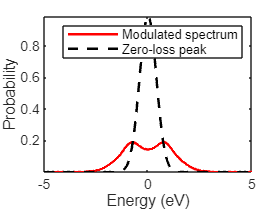

if interaction == "Tx" || interaction == "Ty"

    % Define energy axis (eV)
    E_range = -5:0.01:5; % Energy shift range (eV)
    P_range = zeros(size(E_range));
    prob = zeros(size(E_range));
    n_max = 40; % Maximum number of sidebands

    % Electron path just outside of taper surface
    r_electron = resolution/2 + round(resolution/2 * r / grid_size); 

    % % Electron path just next to taper end facet (through the middle of the
    % % field)
    % r_electron = resolution/2; 

    % Extract field along electron path
    if interaction == "Tx"
        E_path = E_x(r_electron, :);
    end 

    if interaction == "Ty"
        E_path = -E_y(:, r_electron)';
    end 

    % Compute PINEM field 
    phase_shift = deg2rad(0);
    F_int = E_path .* exp(-1i * (k_e .* x - phase_shift));
    F = trapz(x, F_int);
    F_abs = abs(F);

    % Compute coupling strength  
    g = (q / (hbar * omega)) * F_abs; 

    % Compute Probability Distribution

    for n = -n_max:n_max
        E_n = n * (hbar_eV * omega); % Energy shift for order n
        [~, idx] = min(abs(E_range - E_n)); % Find closest index in energy range
        prob(idx) = (besselj(n, g))^2; % Bessel function probability

        P_range = P_range + gauss(E_range, prob(idx), E_n, dE_el/(2*sqrt(2*log(2))));
    end

    P_z0 = (besselj(0, g))^2;
    P_range = 0.5*(P_range + gauss(E_range, P_z0, 0, dE_el/(2*sqrt(2*log(2)))));

    % Zero-Loss Peak
    zero_loss_peak = gauss(E_range, 1, 0, dE_el/(2*sqrt(2*log(2))));

    % % Plot E-field along electron path
    % figure; hold on; box on;
    % plot(x * 1e6, E_path, 'r', 'LineWidth', 1.5); 
    % xline([-b*1e6 -a*1e6 a*1e6 b*1e6],'--');
    % title('E along electron path');
    % xlabel('Radial distance (\mum)');
    % ylabel('Field strength (V/m)');

    % % Plot F_integrand along electron path
    % figure; hold on
    % plot(x * 1e6, real(F_int), 'r', 'LineWidth', 2); 
    % plot(x * 1e6, imag(F_int), 'b', 'LineWidth', 2);
    % xline([-b*1e6 -a*1e6 a*1e6 b*1e6],'--');
    % title(['F_{int}, E_{el} = ',num2str(E_el/1e3),' keV,', ' \phi_{el} = ',num2str(rad2deg(phase_shift)), '°']);
    % xlabel('Radial distance (\mum)');
    % ylabel('Field strength (V/m)');
    % legend('Real','Imag');
    % grid on;

    disp(['PINEM Field |F|: ', num2str(F_abs)]);
    disp(['Coupling strength: ', num2str(g)]);

    % Plot PINEM Spectrum
    figure; hold on; box on;
    plot(E_range, P_range, 'r', 'LineWidth', 1.5, 'DisplayName', 'Modulated spectrum');
    plot(E_range, zero_loss_peak, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Zero-loss peak');
    xlabel('Energy (eV)');
    ylabel('Probability');
    axis tight;
    legend show;
    
    hold off;
end


% matlab2tikz('D:\Documents\Study\Graduation project\MATLAB\Export\PINEM_Ex_spectrum.tex',...
%     'relativeDataPath', 'Figures','showInfo', false,...
%     'extraAxisOptions', 'width=\linewidth');

## Longitudinal PINEM-probability

if interaction == "Lz"

    % Define energy axis (eV)
    E_range = -5:0.01:5; % Energy shift range (eV)
    P_range = zeros(size(E_range));
    prob = zeros(size(E_range));
    n_max = 40; % Maximum order of Bessel function sidebands
    
    % Define electron path height index and interaction length
    r_electron = resolution/2 + round(resolution/4 * r / MFD); 
    L = 8e-6;
    L_z = linspace(0, L, 500);
    
    % Extract field along electron path
    E_path = E_z(resolution/2, r_electron) * ones(size(L_z));
    
    % % Compute PINEM field 
    % F_z = trapz(L_z, E_path .* exp(-1i * k_e * L_z));
    % F_z_abs = abs(F_z);

    F_z_dep = abs(1i * E_path(1,1) / k_e * (exp(-1i * k_e * L_z) - 1));
    F_z_max = max(F_z_dep(:));
    F_z_av = F_z_max * 0.64;
     
    figure; 
    plot(L_z * 1e6, E_path, 'b', 'LineWidth', 2); 
    title('|E_z| versus L_z');
    xlabel('Interaction length (\mum)');
    ylabel('Field strength (V/m)');
    grid on;

    figure; 
    plot(L_z * 1e6, F_z_dep, 'b', 'LineWidth', 2); 
    title('|F_z| versus L_z');
    xlabel('Interaction length (\mum)');
    ylabel('Field strength (a.u.)');
    grid on;
    
    % Compute coupling strength 
    g = (q / (hbar * omega)) * F_z_max; 
    
    disp(['PINEM Field |F_z|: ', num2str(F_z_max)]);
    disp(['Coupling strength: ', num2str(g)]);
    
    % Compute Probability Distribution
    
    for n = -n_max:n_max
        E_n = n * (hbar_eV * omega); % Energy shift for order n
        [~, idx] = min(abs(E_range - E_n)); % Find closest index in energy range
        prob(idx) = (besselj(n, g))^2; % Bessel function probability
    
        P_range = P_range + gauss(E_range, prob(idx), E_n, dE_el/(2*sqrt(2*log(2))));
    end
    
    P_z0 = (besselj(0, g))^2;
    P_range = 0.5*(P_range + gauss(E_range, P_z0, 0, dE_el/(2*sqrt(2*log(2)))));
    
    % Zero-Loss Peak
    zero_loss_peak = gauss(E_range, 1, 0, dE_el/(2*sqrt(2*log(2))));
    
    % Plot PINEM Spectrum
    figure; hold on;
    plot(E_range, P_range, 'b', 'LineWidth', 1.5, 'DisplayName', 'Modulated spectrum');
    plot(E_range, zero_loss_peak, 'g--', 'LineWidth', 1.5, 'DisplayName', 'Zero-loss peak');
    xlabel('Energy Shift (eV)');
    ylabel('Probability');
    title('Longitudinal PINEM Spectrum');
    grid on;
    axis tight;
    legend show;
    hold off;
end 

drawnow;
